load CrackData.mat

cutoffArea = 4000;

crackData.Risk = discretize(crackData.Area,[0,cutoffArea,inf], ...
    "categorical",["Mild","Severe"]);

crackData.MaxWidth = crackData.MaxWidth * 0.5;
crackData.Area = crackData.Area * 0.5 * 0.5;
idx = crackData.Risk == "Mild";
mildData = crackData(idx, :);
idx = crackData.Risk == "Severe";
severeData = crackData(idx, :);
mildMeanWidth = mean(mildData.MaxWidth);
severeMeanWidth = mean(severeData.MaxWidth);


severeMedianWidth = median(severeData.MaxWidth)

severeMedianWidth = single
17.4642

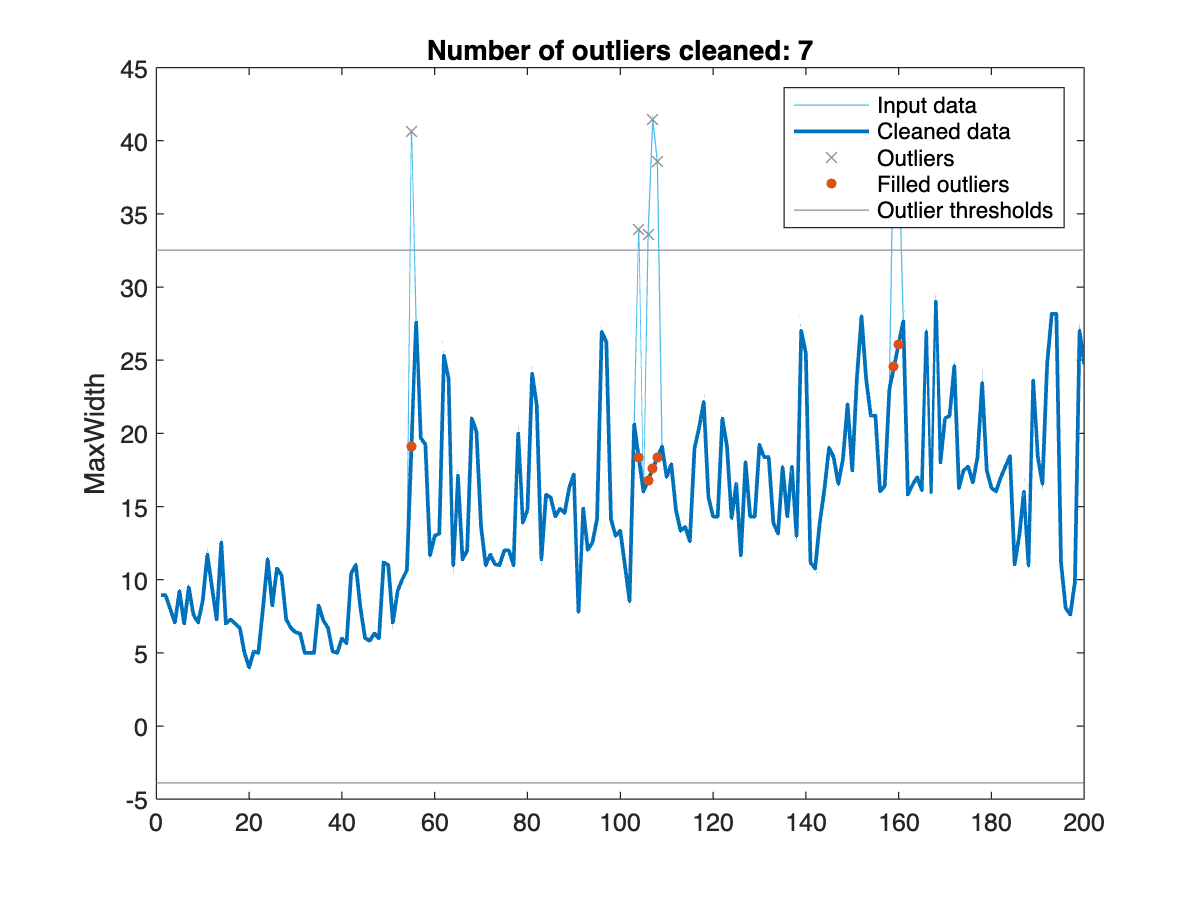

% Fill outliers
[newTable,outlierIndices,lo,hi] = filloutliers(crackData,"linear", ...
    "DataVariables","MaxWidth");

% Display results
figure
plot(crackData.MaxWidth,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(newTable.MaxWidth,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices(:,3)),crackData.MaxWidth(outlierIndices(:,3)),"x", ...
    "Color",[145 145 145]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(find(outlierIndices(:,3)),newTable.MaxWidth(outlierIndices(:,3)),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim], ...
    [lo.MaxWidth lo.MaxWidth missing hi.MaxWidth hi.MaxWidth], ...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,3)))
legend
ylabel("MaxWidth")

clear lo hi

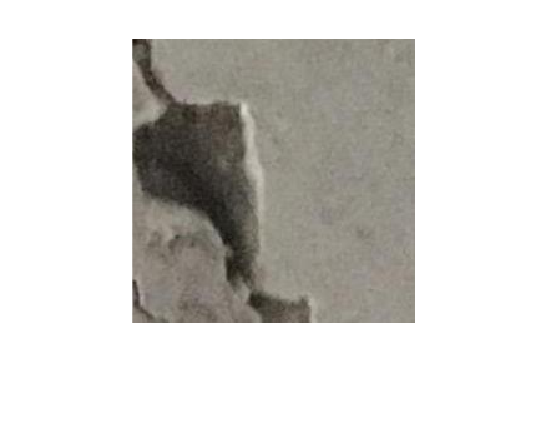

imshow(imread(crackData(108,:).fileName))